# **R-factor: Compare vertical displacement**

## Introduction

Several models were generated with COMSOL

- Model 5 - Homogeneous model

- Model 6 - Groningen model, different permeability on top and bottom of the reservoir

- Model 7 - Groningen model, the same permeability on top and bottom of the reservoir

This script visualize changes due to fluid production for Model 5

**Authors**: Ivan Abakumov

**Publication date**: 25th of February 2020

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

Results5 = MLD('/home/ivan/Desktop/Comsol/My_model_5_results.mat');
Results7 = MLD('/home/ivan/Desktop/Comsol/My_model_7_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_7_G_file.mat');

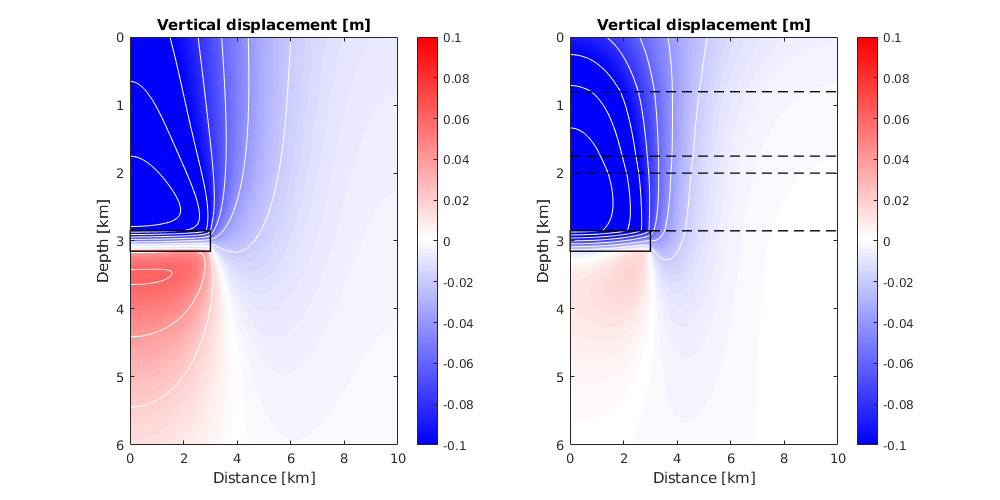

tt = 101;

figure(1)
fig = figure('Position', [1 1 1000 500]);
subplot(1,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Results5.disp_y(:,:,tt)'-Results5.disp_y(:,:,1)')
hold on 
contour(G.xx/1e3, G.zz/1e3, Results5.disp_y(:,:,tt)'-Results5.disp_y(:,:,1)', 'ShowText', 'off', 'Color', 'white')
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-0.1 0.1])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical displacement [m]')

subplot(1,2,2)
imagesc(G.xx/1e3, G.zz/1e3, Results7.disp_y(:,:,tt)'-Results7.disp_y(:,:,1)')
hold on 
contour(G.xx/1e3, G.zz/1e3, Results7.disp_y(:,:,tt)'-Results7.disp_y(:,:,1)', 'ShowText', 'off', 'Color', 'white')
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-0.1 0.1])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Vertical displacement [m]')